# Fault Fearture Frequency 


% DE - drive end accelerometer data
% FE - fan end accelerometer data

% Normal
load('Normal_2_099.mat')

% Inner Race
load('IR007_2_280.mat')

% Outer Race
load("OR007@6_2_296.mat")

% Ball
load("B014_2_288.mat")
fs12k = 12000;

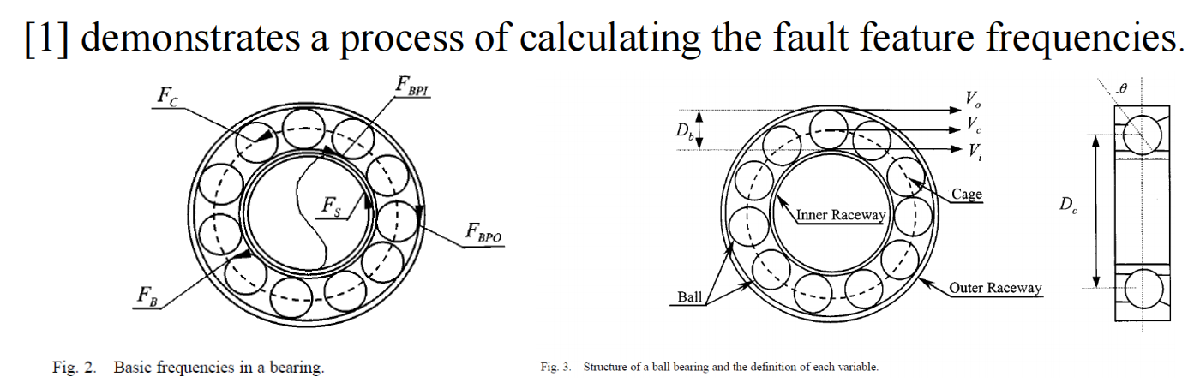

Fs：滚动体转速

Dc：滚动轴承的节圆直径

Db：Ball Fault Diameter (inches)

Nb: Number of Ball 

Nb = 8;
Db = 0.2656;
Dc = 1.122; 
Fs = 1755/60;

% Inner Race
Fc =   Fs * (1 - Db/Dc);
Fbpo = (Nb/2) * Fs * (1 - Db/Dc);
Fbpi = (Nb/2) * Fs * (1 + Db/Dc);
Fb = Dc/(2*Db) * Fs * (1 - Db^2/Dc^2);

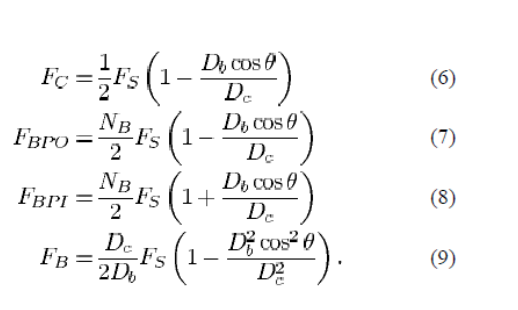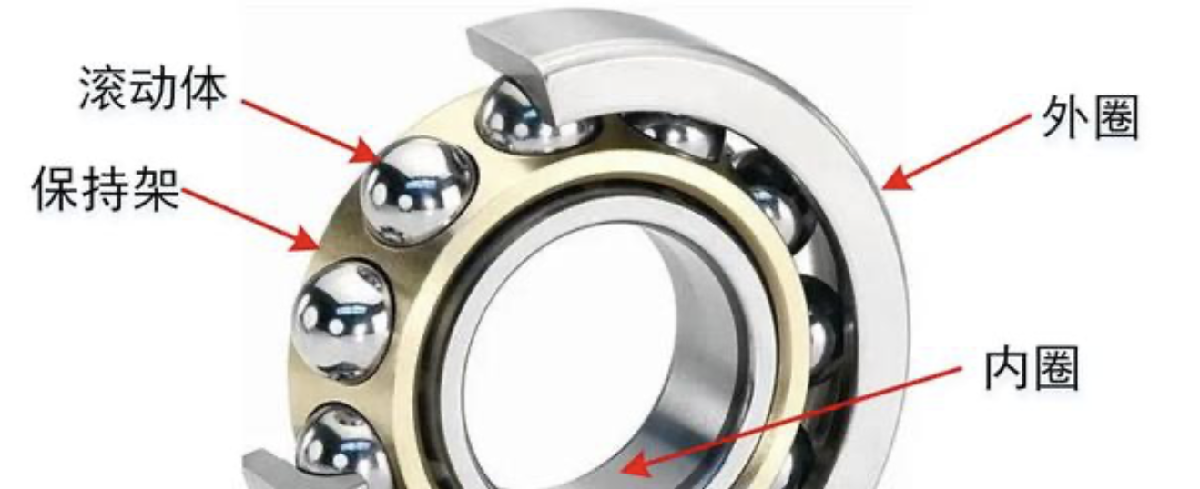

Fc：保持架故障特征频率

Fbpo:外圈故障特征频率

Fbpi:内圈故障特征频率

Fb：滚动体故障频率

## Normal Data Load

% time domain
n_data_size = size(X099_DE_time,1)

n_data_size = 485063

t_n = 0:1/fs12k:(n_data_size - 1)/fs12k

t_n =          0    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0018    0.0019    0.0020    0.0021    0.0022    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0037    0.0038    0.0039    0.0040    0.0041


Normal_DE = X099_DE_time(:,1);
subplot(2,1,1)
plot(t_n,Normal_DE)
xlabel('t'); ylabel('Normal DE');

% FFT
FFT_N = fft(Normal_DE);
L_N = length(Normal_DE);
Spectrum_n = abs(FFT_N(1:(L_N/2+1),1))/L_N*2;


subplot(2,1,2)
xlim([0 6000])
ylim([0.039 0.079])
plot((0:L_N/2)/L_N*fs12k,Spectrum_n)
xlabel('Frequency (Hz)'); ylabel('Normal Amplitude')
title('Normal Race FFT');